# VAV Assignment 01 - A.Y. 2023/24

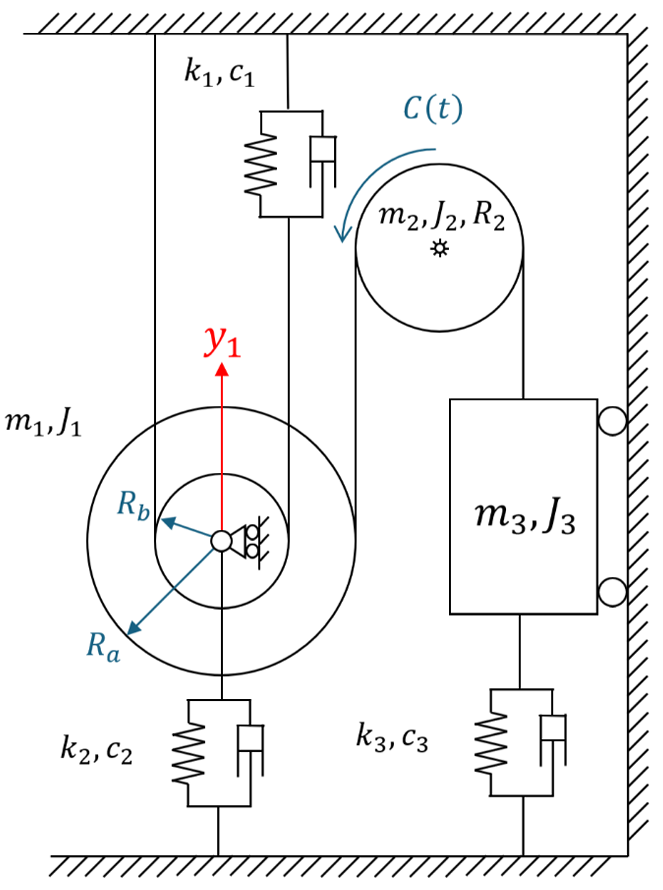

% Variables definition

M_1 = 15;       % [Kg]
M_2 = 10;       % [Kg]
M_3 = 5;        % [Kg]
J_1 = 10;       % [Kg*m^2]
J_2 = 8;        % [Kg*m^2]
J_3 = 10;       % [Kg*m^2]
R_a = 0.8;      % [m]
R_b = 0.5;      % [m]
R_2 = 0.6;      % [m]
c_1 = 30;       % [N*s/m]
c_2 = 40;       % [N*s/m]
c_3 = 50;       % [N*s/m]
k_1 = 2600;     % [N/m]
k_2 = 2000;     % [N/m]
k_3 = 1600;     % [N/m]


% 1A. EoM for small vibrations around static equilibrium

M_eq = M_1 + M_3*((R_a + R_b)/R_b)^2 + J_1/(R_b^2) + J_2*((R_a + R_b)/(R_2*R_b))^2;   % equivalent mass in the kinetic energy, [Kg]
c_eq = c_1*4 + c_2 + c_3*((R_a + R_b)/R_b)^2;     % equivalent damping in the dissipative function, [N*s/m]
k_eq = k_1*4 + k_2 + k_3*((R_a + R_b)/R_b)^2;     % equivalent stiffness in the potential elastic energy, [N/m]
% m_eq = M_1 + M_3*((R_a + R_b)/R_b);           % potential gravitational energy
Q = -(R_a + R_b)/(R_2*R_b);     % coefficient of torque Lagrangian component [m^(-1)]

% 1B. Natural frequency

w_0 = sqrt(k_eq/M_eq); % [rad/s]

% 1C. Adimensional damping factor and frequency of damped system

alpha = c_eq/(2*M_eq);  % [rad/s]
h = alpha/w_0;
w_d = w_0*sqrt(1-h^2);% [rad/s]


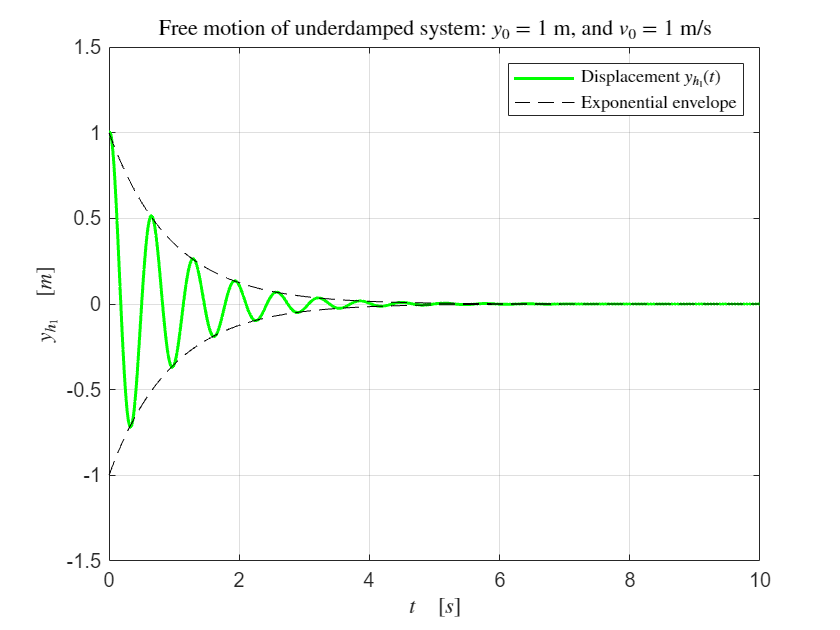

% 2A. Free motion

y_0 = 1;    % [m]
v_0 = 1;    % [m/s]
t = 0 : 1/10000 : 20;

% Displacement in time
y_1g = exp(-alpha.*t).*(y_0*cos(w_d.*t) + (v_0 + alpha*y_0)/w_d*sin(w_d.*t));

figure()
plot(t, y_1g, "green", "LineWidth", 1.5);
grid on
hold on
plot(t, exp(-alpha.*t), "--k");
plot(t, -exp(-alpha.*t), "--k");
strTitle = ['Free motion of underdamped system: $y_0 = $', num2str(y_0), ' m, and $v_0 = $', num2str(v_0), ' m/s'];
title(strTitle, "Interpreter", "latex");
xlabel("$t \quad [s]$", "Interpreter", "latex");
ylabel("$y_{h_1} \quad [m]$", "Interpreter", "latex");
xlim([0 10]);
ylim([-y_0-0.5 y_0+0.5]);
legend("Displacement $y_{h_1}(t)$", "Exponential envelope", "Interpreter", "latex");

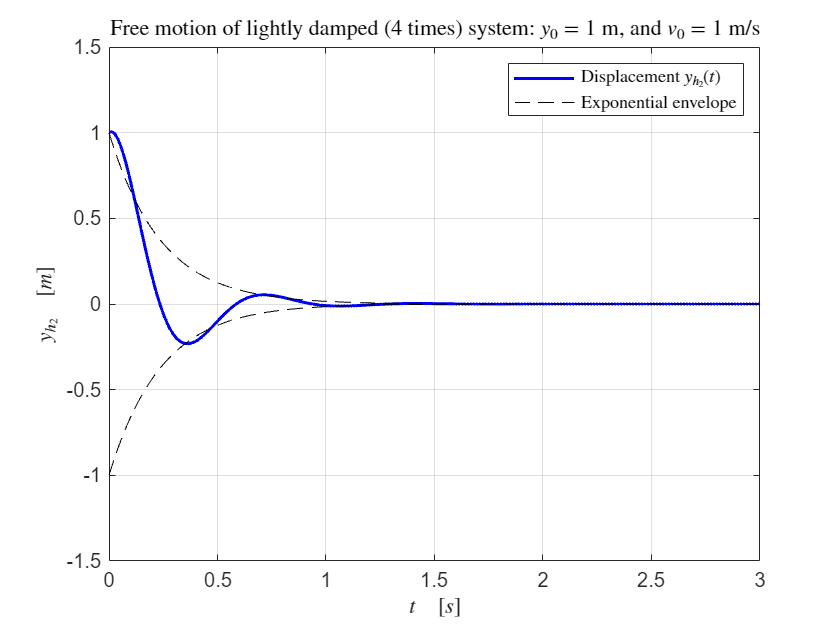


% 2B. New adimensional damping ratio (4 times)

h_2 = 4*c_eq/(2*M_eq*w_0);
alpha_2 = h_2*w_0;              % [rad/s]
w_d2 = w_0*sqrt(1-h_2^2);	    % [rad/s]

% Displacement in time
y_2 = exp(-alpha_2.*t).*(y_0*cos(w_d2.*t) + (v_0 + alpha_2*y_0)/w_d2*sin(w_d2.*t));

figure()
plot(t, y_2, "blue", "LineWidth", 1.5);
grid on
hold on
plot(t, exp(-alpha_2.*t), "--k");
plot(t, -exp(-alpha_2.*t), "--k");
strTitle = ['Free motion of lightly damped (4 times) system: $y_0 = $', num2str(y_0), ' m, and $v_0 = $', num2str(v_0), ' m/s'];
title(strTitle, "Interpreter", "latex");
xlabel("$t \quad [s]$", "Interpreter", "latex");
ylabel("$y_{h_2} \quad [m]$", "Interpreter", "latex");
xlim([0 3]);
ylim([-y_0-0.5 y_0+0.5]);
legend("Displacement $y_{h_2}(t)$", "Exponential envelope", "Interpreter", "latex");

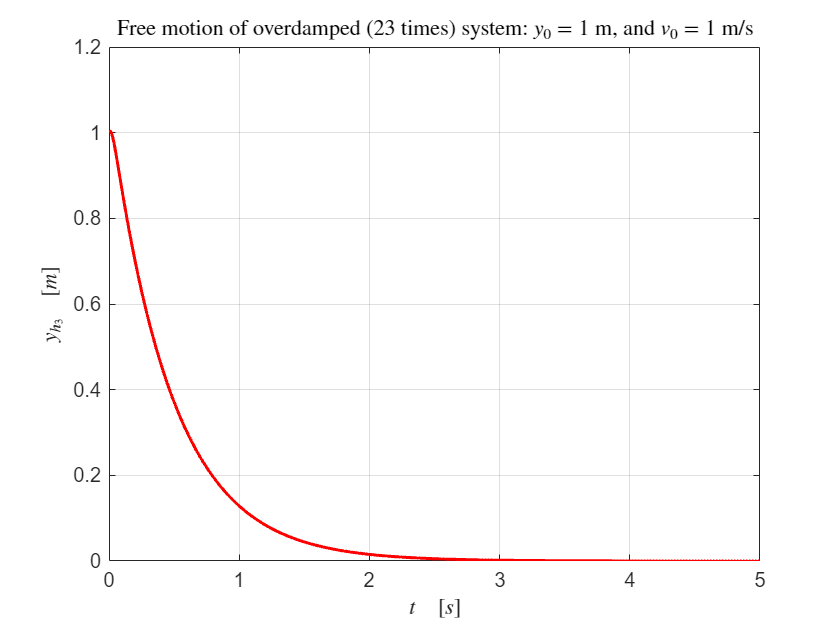


% 2C. New adimensional damping ratio (23 times)

alpha_3 = 23*c_eq/(2*M_eq); % [rad/s]

a_1 = alpha_3 + sqrt(alpha_3^2 - w_0^2);    % [rad/s]
a_2 = alpha_3 - sqrt(alpha_3^2 - w_0^2);    % [rad/s]

% Displacement in time
y_3 = -(v_0 + a_2*y_0)/(a_1-a_2)*exp(-a_1.*t) + (v_0 + a_1*y_0)/(a_1-a_2)*exp(-a_2.*t);

figure()
plot(t, y_3, "red", "LineWidth", 1.5);
grid on
strTitle = ['Free motion of overdamped (23 times) system: $y_0 = $', num2str(y_0), ' m, and $v_0 = $', num2str(v_0), ' m/s'];
title(strTitle, "Interpreter", "latex");
xlabel("$t \quad [s]$", "Interpreter", "latex");
ylabel("$y_{h_3} \quad [m]$", "Interpreter", "latex");
xlim([0 5]);

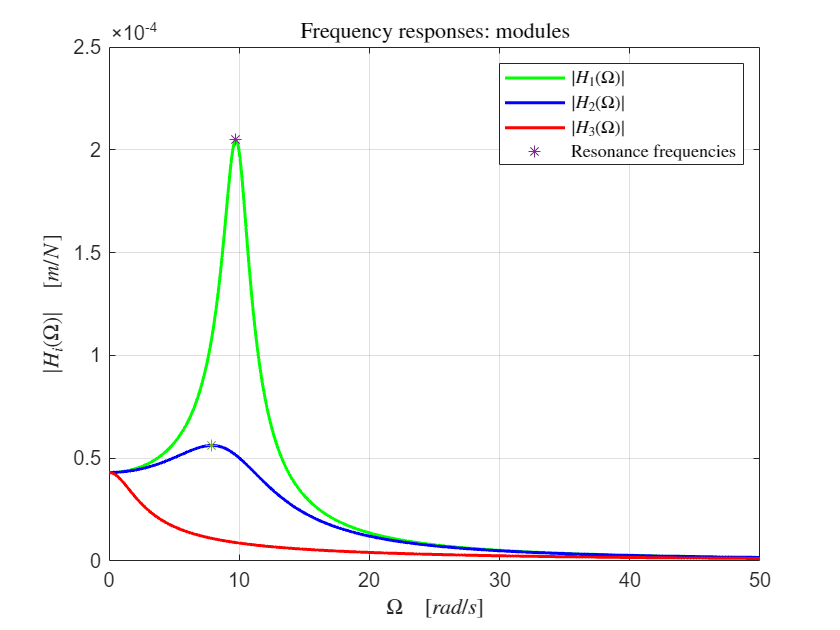

% 3A. Forced motion

W = 0 : 0.001 : 200;

frf_1 = (1/M_eq)./(w_0^2 - W.^2 + 2i*alpha.*W);
[frf_max, frf_index] = max(abs(frf_1));

% Adimensional damping ratio 4 times

frf_2 = (1/M_eq)./(w_0^2 - W.^2 + 2i*alpha_2.*W);
[frf_max2, frf_index2] = max(abs(frf_2));

% Adimensional damping ratio 23 times

frf_3 = (1/M_eq)./(w_0^2 - W.^2 + 2i*alpha_3.*W);
[frf_max3, frf_index3] = max(abs(frf_3));

% Magnitudes plot
figure()
plot(W, abs(frf_1), "green", "LineWidth", 1.5);
hold on
plot(W, abs(frf_2), "blue", "LineWidth", 1.5);
plot(W, abs(frf_3), "red", "LineWidth", 1.5);
plot(W(frf_index), frf_max, "*");
plot(W(frf_index2), frf_max2, "*");
grid on
title("Frequency responses: modules", "Interpreter", "latex");
xlabel("$\Omega \quad [rad/s]$", "Interpreter", "latex");
ylabel("$|H_i(\Omega)| \quad [m/N]$", "Interpreter", "latex");
xlim([0 50]);
legend("$|H_1(\Omega)|$", "$|H_2(\Omega)|$", "$|H_3(\Omega)|$", "Resonance frequencies", "Interpreter", "latex");

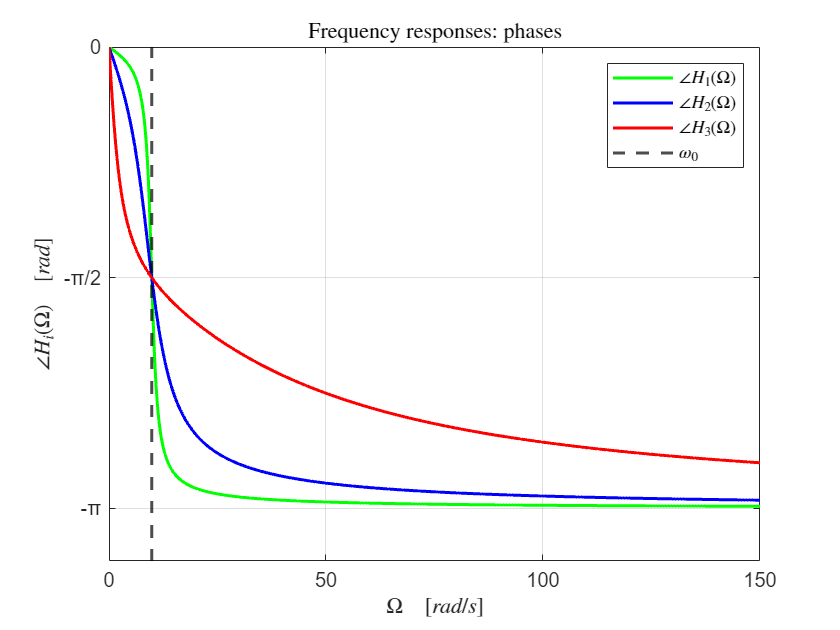


% Phases plot
figure()
plot(W, angle(frf_1), "green", "LineWidth", 1.5);
hold on
plot(W, angle(frf_2), "blue", "LineWidth", 1.5);
plot(W, angle(frf_3), "red", "LineWidth", 1.5);
xline(w_0, "--k", "LineWidth", 1.5);
yticks([-pi -pi/2 0]);
yticklabels(["-π" "-π/2" "0"]);
grid on
title("Frequency responses: phases", "Interpreter", "latex");
xlabel("$\Omega \quad [rad/s]$", "Interpreter", "latex");
ylabel("$\angle{H_i(\Omega)} \quad [rad]$", "Interpreter", "latex");
xlim([0 150]);
legend("$\angle{H_1(\Omega)}$", "$\angle{H_2(\Omega)}$", "$\angle{H_3(\Omega)}$", "$\omega_0$", "Interpreter", "latex");

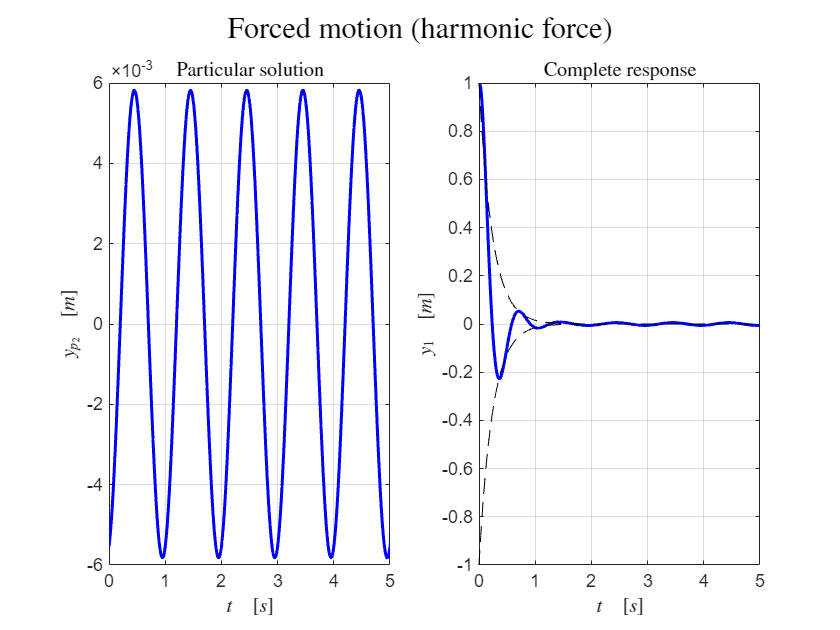


% 3B. Complete time response

A = 25;     % [N*m]
f = 1;      % [Hz]
phi = pi/3; % [rad]

%Q = -(R_a + R_b)/(R_2*R_b);    % coefficient of torque Lagrangian component [m^(-1)]
F_0 = A*Q;          % [N]

% Frequency response for f=1
h_f = (1/M_eq)/(w_0^2 - (2*pi*f)^2 + 2i*alpha_2*(2*pi*f));

% Steady-state response (particular)
y_p = abs(h_f) * F_0 * cos(2*pi*f.*t + phi + angle(h_f));

% Complete response (homogeneous + particular)
y = y_2 + y_p;

figure()
sgtitle("Forced motion (harmonic force)", "Interpreter", "latex");
subplot(1, 2, 1);
plot(t, y_p, "blue", "LineWidth", 1.5);
grid on
title("Particular solution", "Interpreter", "latex");
xlabel("$t \quad [s]$", "Interpreter", "latex");
ylabel("$y_{p_2} \quad [m]$", "Interpreter", "latex");
xlim([0 5]);

subplot(1, 2, 2);
plot(t, y, "blue", "LineWidth", 1.5);
grid on
hold on
plot(t, exp(-alpha_2.*t), "--k");
plot(t, -exp(-alpha_2.*t), "--k");
title("Complete response", "Interpreter", "latex");
xlabel("$t \quad [s]$", "Interpreter", "latex");
ylabel("$y_1 \quad [m]$", "Interpreter", "latex");
xlim([0 5]);
ylim([-y_0 y_0]);

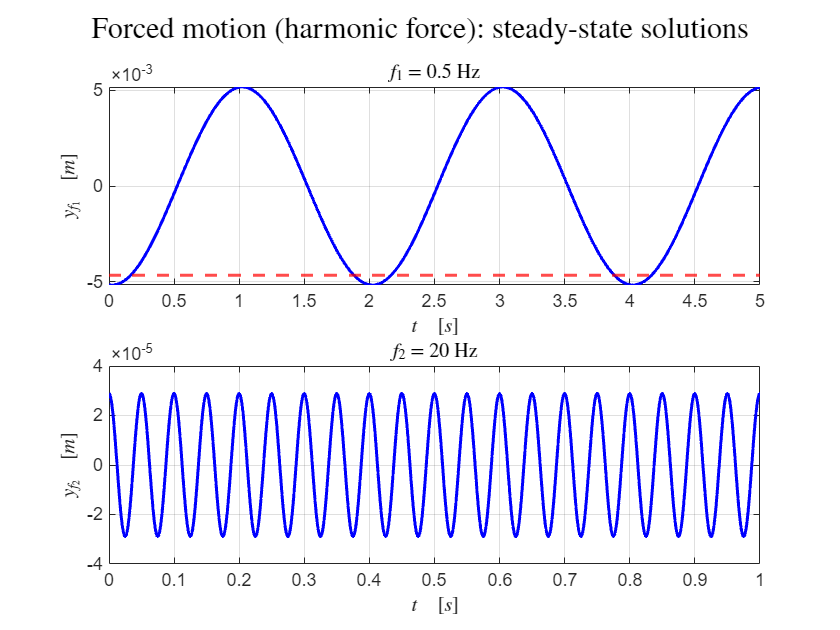


% 3C. Steady-state solution with different frequencies

f_1 = 0.5;  % [Hz]
f_2 = 20;   % [Hz]

% Frequency response frequency 1
h_f1 = (1/M_eq)/(w_0^2 - (2*pi*f_1)^2 + 2i*alpha*(2*pi*f_1));

% Frequency response frequency 2
h_f2 = (1/M_eq)/(w_0^2 - (2*pi*f_2)^2 + 2i*alpha*(2*pi*f_2));

% Solution frequency 1
y_f1 = abs(h_f1) * F_0 * cos(2*pi*f_1.*t + angle(h_f1));

% Solution frequency 2
y_f2 = abs(h_f2) * F_0 * cos(2*pi*f_2.*t + angle(h_f2));

% Frequency response static (f=0)
h_fst = 1/k_eq;

% Solution static torque
y_st = h_fst * F_0;

figure()
sgtitle("Forced motion (harmonic force): steady-state solutions", "Interpreter", "latex");

subplot(2, 1, 1);
plot(t, y_f1, "blue", "LineWidth", 1.5);
xlim([0  5]);
grid on
hold on
yline(y_st, "--r", "LineWidth", 1.5);
title("$f_1$ = 0.5 Hz", "Interpreter", "latex");
xlabel("$t \quad [s]$", "Interpreter", "latex");
ylabel("$y_{f_1} \quad [m]$", "Interpreter", "latex");

subplot(2, 1, 2);
plot(t, y_f2, "blue", "LineWidth", 1.5);
xlim([0  1]);
grid on
hold on
title("$f_2$ = 20 Hz", "Interpreter", "latex");
xlabel("$t \quad [s]$", "Interpreter", "latex");
ylabel("$y_{f_2} \quad [m]$", "Interpreter", "latex");

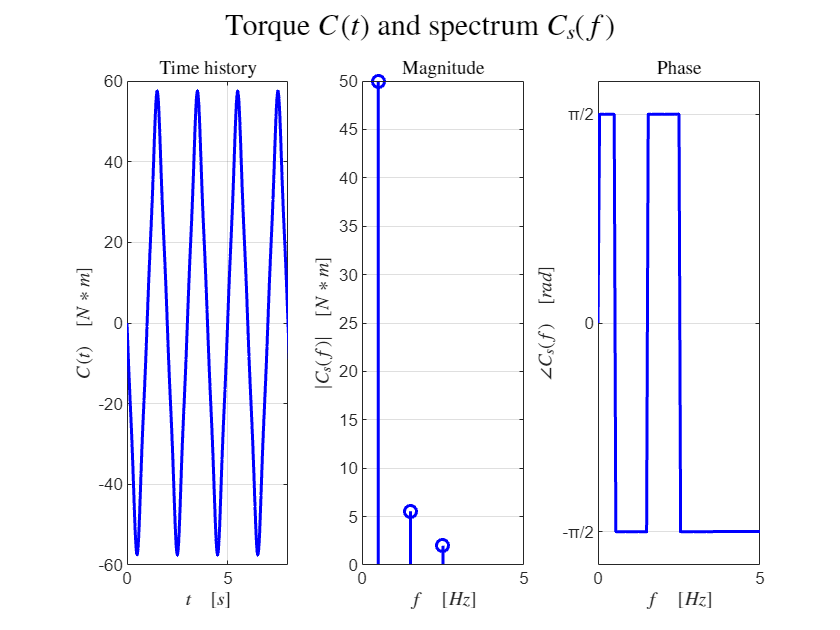


% #########################################################################################
% Complete response f_1
%y_1 = y_1g + y_f1;

%figure()
%plot(t, y_1, "green", "LineWidth", 1.5);
%grid on
%hold on
%title("Forced motion (harmonic forces $f_1$ and $f_2$): complete response", "Interpreter", "latex");

% Complete response f_2
%y_2 = y_1g + y_f2;

%plot(t, y_2, "blue");
%plot(t, exp(-alpha.*t), "--k");
%plot(t, -exp(-alpha.*t), "--k");
%xlabel("$t \quad [s]$", "Interpreter", "latex");
%ylabel("$y_{f_i} \quad [m]$", "Interpreter", "latex");
%xlim([0 10]);
%ylim([-1.2 1.2]);
%legend("$y_{f_1}$", "$y_{f_2}$", "Exponential envelope", "Interpreter", "latex");
% #########################################################################################

% 3D. Harmonic superposition

% Amplitudes
B_1 = 50;       % [N.m]
B_2 = 5.55;     % [N.m]
B_3 = 2;        % [N.m]

% Frequencies
f_1b = 0.5;     % [Hz]
f_2b = 1.5;     % [Hz]
f_3b = 2.5;     % [Hz]

% Phases
phi_1b = pi/2;  % [rad]
phi_2b = -pi/2; % [rad]
phi_3b = pi/2;  % [rad]

% Torque time history and spectrum
c = B_1 * cos(2*pi*f_1b.*t + phi_1b) + B_2 * cos(2*pi*f_2b.*t + phi_2b) + B_3 * cos(2*pi*f_3b.*t + phi_3b);
C = fft(c);

% Frequency domain plot
N = length(c);      % [samples]
fs = 10000;         % [Hz]
f_axis = (0:N-1) * (fs/N);

% Magnitude spectrum filtering
filtered_C = C;
filtered_C = abs(filtered_C)/(N/2);         % switching the components of C back into [N*m] units
filtered_C(abs(filtered_C)<0.05 )= NaN;     % cleaning the low component values

% Torque plot
figure()
sgtitle("Torque $C(t)$ and spectrum $C_s(f)$", "Interpreter", "latex");
    
subplot(1, 3, 1);
plot(t, c, "blue", "LineWidth", 1.5);
title("Time history", "Interpreter", "latex");
grid on
%hold on
%plot(t, B_1 * cos(2*pi*f_1b.*t + phi_1b), "blue", "LineWidth", 1.5);
%plot(t, B_2 * cos(2*pi*f_2b.*t + phi_2b), "red", "LineWidth", 1.5);
%plot(t, B_3 * cos(2*pi*f_3b.*t + phi_3b), "cyan", "LineWidth", 1.5);
xlabel("$t \quad [s]$", "Interpreter", "latex");
ylabel("$C(t) \quad [N*m]$", "Interpreter", "latex");
xlim([0 8]);

subplot(1, 3, 2);
stem(f_axis, filtered_C, "blue", "LineWidth", 1.5);
title("Magnitude", "Interpreter", "latex");
xlim([0 5]);
grid on
xlabel("$f \quad [Hz]$", "Interpreter", "latex");
ylabel("$|C_s(f)| \quad [N*m]$", "Interpreter", "latex");

subplot(1, 3, 3);
plot(f_axis, angle(C), "blue", "LineWidth", 1.5);
title("Phase", "Interpreter", "latex");
xlim([0 5]);
ylim([-(pi/2)-0.25 (pi/2)+0.25]);
yticks([-pi/2 0 pi/2]);
yticklabels(["-π/2" "0" "π/2"]);
grid on
xlabel("$f \quad [Hz]$", "Interpreter", "latex");
ylabel("$\angle{C_s(f)} \quad [rad]$", "Interpreter", "latex");

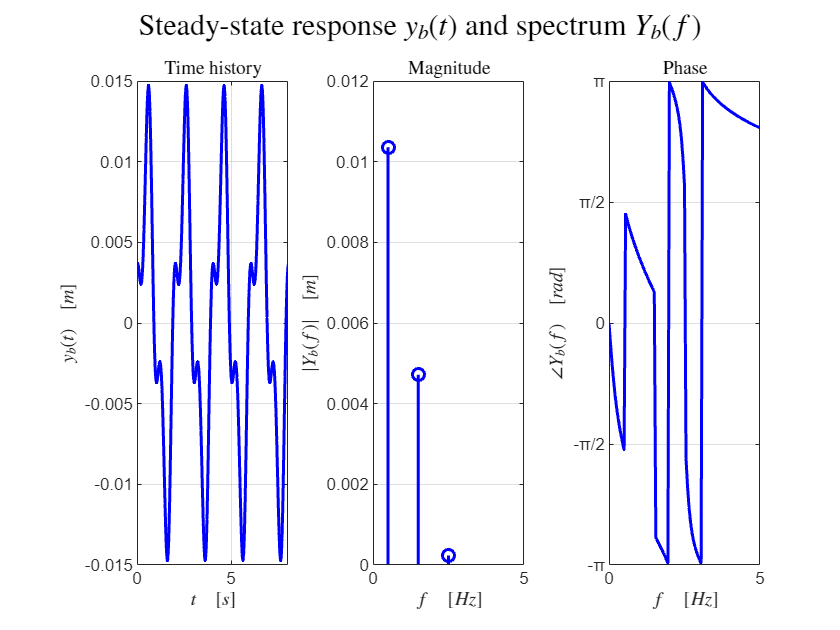


% Frequency responses
h_f1b = (1/M_eq)/(w_0^2 - (2*pi*f_1b)^2 + 2i*alpha*(2*pi*f_1b));
h_f2b = (1/M_eq)/(w_0^2 - (2*pi*f_2b)^2 + 2i*alpha*(2*pi*f_2b));
h_f3b = (1/M_eq)/(w_0^2 - (2*pi*f_3b)^2 + 2i*alpha*(2*pi*f_3b));

% Steady-state solutions
y_b1 = abs(h_f1b) * B_1 * Q * cos(2*pi*f_1b.*t + phi_1b + angle(h_f1b));
y_b2 = abs(h_f2b) * B_2 * Q * cos(2*pi*f_2b.*t + phi_2b + angle(h_f2b));
y_b3 = abs(h_f3b) * B_3 * Q * cos(2*pi*f_3b.*t + phi_3b + angle(h_f3b));

% Steady-state time history and spectrum
y_b = y_b1 + y_b2 + y_b3;
Y_b = fft(y_b);

% Frequency domain plot
N = length(y_b);        % [samples]
fs = 10000;             % [Hz]
f_axis = (0:N-1) * (fs/N);

% Magnitude spectrum filtering
filtered_Yb = abs(Y_b)/(N/2);               % switching the components of Y_b back into [N*m] units
filtered_Yb(abs(filtered_Yb)<5e-5)=NaN;

figure()
sgtitle("Steady-state response $y_b(t)$ and spectrum $Y_b(f)$", "Interpreter", "latex");

subplot(1, 3, 1);
plot(t, y_b, "blue", "LineWidth", 1.5);
title("Time history", "Interpreter", "latex");
grid on
xlabel("$t \quad [s]$", "Interpreter", "latex");
ylabel("$y_b(t) \quad [m]$", "Interpreter", "latex");
xlim([0 8])

subplot(1, 3, 2);
stem(f_axis, filtered_Yb, "blue", "LineWidth", 1.5);
title("Magnitude", "Interpreter", "latex");
xlim([0 5]);
grid on
xlabel("$f \quad [Hz]$", "Interpreter", "latex");
ylabel("$|Y_b (f)| \quad [m]$", "Interpreter", "latex");

subplot(1, 3, 3);
plot(f_axis, angle(Y_b), "blue", "LineWidth", 1.5);
ylim([-pi pi]);
title("Phase", "Interpreter", "latex");
xlim([0 5]);
yticks([-pi -pi/2 0 pi/2 pi]);
yticklabels(["-π" "-π/2" "0" "π/2" "π"]);
grid on
xlabel("$f \quad [Hz]$", "Interpreter", "latex");
ylabel("$\angle{Y_b (f)} \quad [rad]$", "Interpreter", "latex");